clear all
close all

x = double(imread('green.jpg'))

x = x(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   253   255   255   255   255   249   253   255   251   250   255   252   248   255   255   254   250   252   255   255   248   224   191   156   122    99    94   100   122   139   151   169   191   192   198   227   228   228   227   226   225   223   222   221   222   222   222   222   222   222   222   222   221   221   221   221   221   221   221   221   220   220   220   220   220   220   220   220   218   218   218   218   218   218   218   218   215   215   215   215   215   215   215   215   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   209   209   209   209   209   209   209   209   208   208   208   208

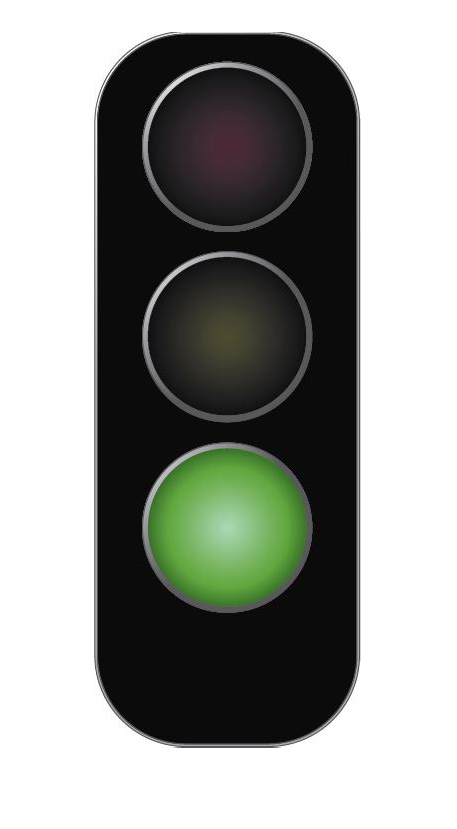

figure,imshow(x/255);

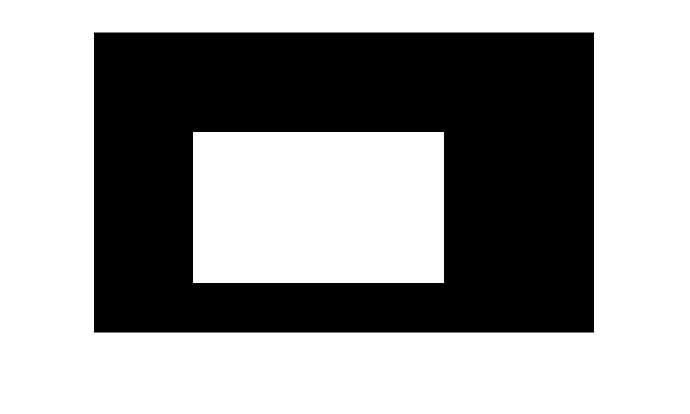


y = x;
a = zeros(300, 500);
a(100:250, 100:350) = 1;
figure,imshow(a)

save m.dat a -ascii

% Digital Water marking

x1 = x(:,:,1);
x2 = x(:,:,2);
x3 = x(:,:,3);

dx1 = dct2(x1); dx11=dx1;

'dct2' requires Image Processing Toolbox.

dx2 = dct2(x2); dx22=dx2;
dx3 = dct2(x3); dx33=dx3;

% Binary Mask for watermaking
load m.dat

g = 10; %coefficient of watermark's strength
[rm, cm] = size(m);
dx1(1:rm, 1:cm) = dx2(1:rm, 1:cm) + g*m;
dx2(1:rm, 1:cm) = dx3(1:rm, 1:cm) + g*m;
dx3(1:rm, 1:cm) = dx3(1:rm, 1:cm) + g*m;

figure,imshow(dx1);
figure,imshow(dx2);
figure,imshow(dx3);

y1 = idct2(dx1);
y2 = idct2(dx2);
y3 = idct2(dx3);
y(:, :, 1) = y1;
y(:, :, 2) = y2;
y(:, :, 3) = y3;

figure,imshow(y1);
figure,imshow(y2);
figure,imshow(y3);
figure,imshow(y);

figure; imshow(y/225)
figure; imshow(abs(y-x)*100) %comparison


z = y;
[r, c, s] = size(z);

% De-Watering;
% Cleaning Image(Knowing Mask)

dy1 = dct2(y(:, :, 1));
dy2 = dct2(y(:, :, 2));
dy3 = dct2(y(:, :, 3));

dy1(1:rm, 1:cm) = dy1(1:rm, 1:cm) - g*m;
dy2(1:rm, 1:cm) = dy2(1:rm, 1:cm) - g*m;
dy3(1:rm, 1:cm) = dy3(1:rm, 1:cm) - g*m;

y11 = idct2(dy1);
y22 = idct2(dy2);
y33 = idct2(dy3);

yy(:, :, 1) = y11;
yy(:, :, 2) = y22;
yy(:, :, 3) = y33;

figure; imshow(yy/255)
figure; imshow(abs(yy-x)*10000)
